# Visualizing a hyper-plane in SVM classifier

This example describes a hyper-plane in support vector machine for classification. This code was created with reference to the official documentation entitled "Support Vector Machines for Binary Classification" as shown below. 

(https://jp.mathworks.com/help/stats/support-vector-machines-for-binary-classification.html?lang=en)

While the officilal document denotes how to show the decision boundary in a 2D space, this example represents how to describe the hype-plane in a 3D space. 

The red translucent boundary dipicts the hyper-plane for the classification. The plots surrounded by "O mark" correspond to support vectors. 

## 1. Load the data and implement Support Vecotor Machine algorithm

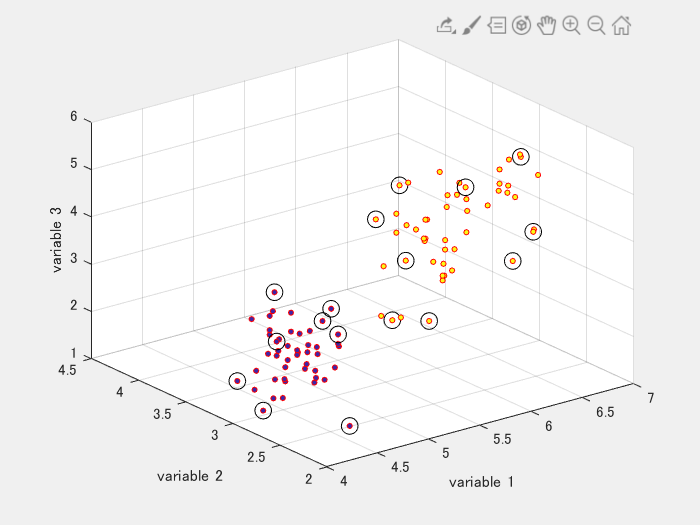

clear;clc;close all
load fisheriris % Load Fisher's iris dataset. 
% the variable "meas" shows the parameter representing flower's shape. 
% the variable species holds the category of each data. 
classPick = ~strcmp(species,'virginica'); % the row of not-virginica has a value 1. 
X = meas(classPick,1:3);% extract the parameters of iris and versicolor
Y = species(classPick);% extract the label information
SVMModel = fitcsvm(X,Y,'KernelFunction','rbf', ...
    'Solver','SMO');% conduct the training of SVM
SupportVector = SVMModel.SupportVectors;
figure
set(gcf,'Visible','on')
scatter3(X(:,1),X(:,2),X(:,3),10,categorical(Y),'filled','MarkerEdgeColor','r' )
xlabel('variable 1');ylabel('variable 2');zlabel('variable 3');
hold on
plot3(SupportVector(:,1),SupportVector(:,2),SupportVector(:,3),'ko','MarkerSize',10)
hold on

## 2. Describing the hyper-plane

- Specify the variable `numGrid` which is a number of points used to search the hyper-plane at each variable 

- The total of `numGrid × numGrid × numGrid `points were prepared and their x, y, z values were listed in the xList

- Higher `numGrid` value leads to the detailed hyper-plane with long processing time, namely, the precision and time are in a trade-off. 

- A plane was described to the area whose scores is near 0, which is the border for the classification

- The function isosurface creats the red translucent plane based on the score value 

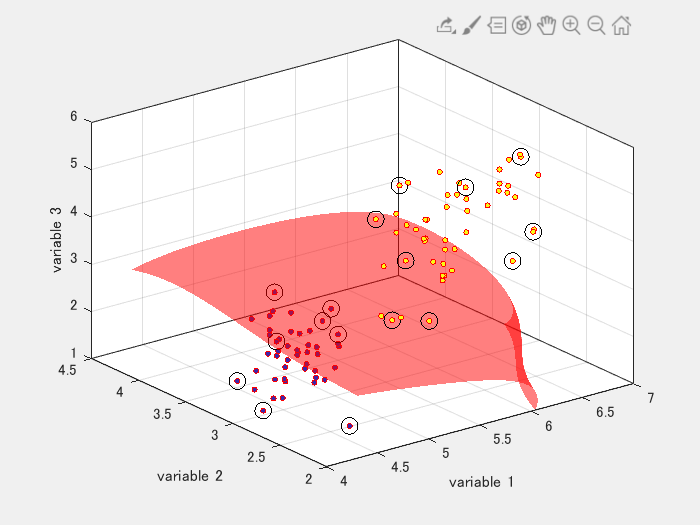

numGrid = 100;
[x1Grid,x2Grid,x3Grid] = meshgrid(linspace(min(X(:,1)),max(X(:,1)),numGrid),...
    linspace(min(X(:,2)),max(X(:,2)),numGrid),linspace(min(X(:,3)),max(X(:,3)),numGrid));
xList = [x1Grid(:),x2Grid(:),x3Grid(:)];
[~,scores] = predict(SVMModel,xList);
[faces,verts] = isosurface(x1Grid,x2Grid,x3Grid, reshape(scores(:,2),size(x1Grid)),0);
p=patch('Vertices', verts, 'Faces', faces, 'FaceColor','k','edgecolor', 'none', 'FaceAlpha', 0.5);
p.FaceColor = 'red';
grid on; box on